# Problem 1

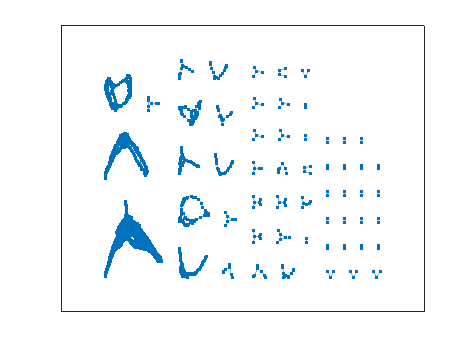

% Loading Data

data = load("usroads.mat");

G = graph(data.Problem.A);
plot(G)

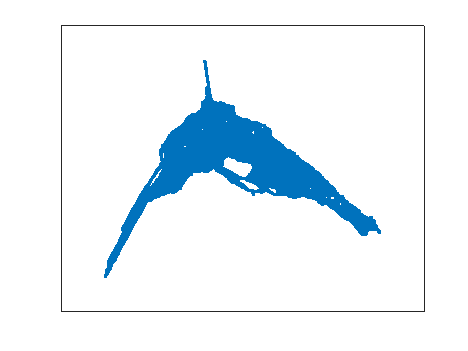

comps = conncomp(G);

SG = subgraph(G, comps==28);

plot(SG)

## Problem 1.1

A_SG = adjacency(SG);

A_SG2= [0 0 0 0 0 0 0 0 1 0 0 0 0 0 0;
0 0 0 0 0 1 1 0 1 0 0 0 0 0 0;
0 0 0 0 1 0 0 0 1 0 0 0 0 0 0;
0 0 0 0 0 0 1 0 0 0 1 0 0 1 0;
0 0 1 0 0 0 0 0 0 0 1 0 0 1 0;
0 1 0 0 0 0 0 0 0 0 0 0 0 0 0;
0 1 0 1 0 0 0 1 0 0 0 0 0 0 1;
0 0 0 0 0 0 1 0 0 0 0 0 0 0 0;
1 1 1 0 0 0 0 0 0 0 0 1 1 0 1;
0 0 0 0 0 0 0 0 0 0 0 0 1 0 0;
0 0 0 1 1 0 0 0 0 0 0 0 0 1 0;
0 0 0 0 0 0 0 0 1 0 0 0 0 1 1;
0 0 0 0 0 0 0 0 1 1 0 0 0 0 0;
0 0 0 1 1 0 0 0 0 0 1 1 0 0 0;
0 0 0 0 0 0 1 0 1 0 0 1 0 0 0];

%A_SG = sparse(A_SG);

A_SG = A_SG./sum(A_SG);

## Problem 1.2

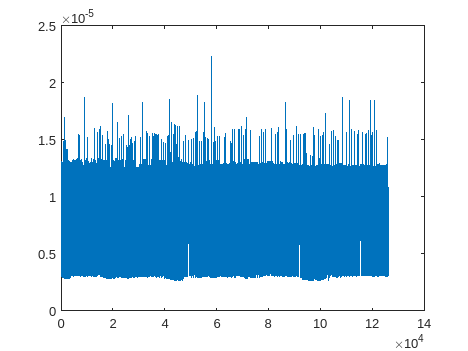

% Power Iteration
% Find the page rank of this network using power iteration.

alpha = 0.9;
n = length(A_SG);
iterations = 1000;

%Begin power iteration
x0=ones(n,1)/n;

for i = 1:iterations
    y0=A_SG*x0;
    x0=y0./sum(y0);
end

pr_pi = x0./sum(x0);
plot(pr_pi)

## Problem 1.3

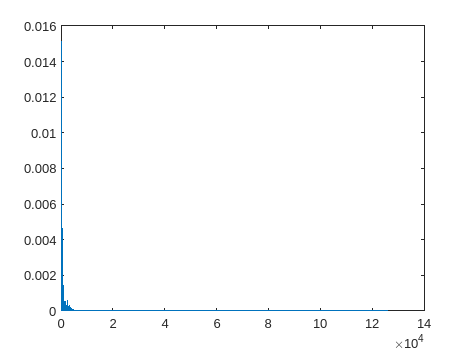

% Solve using the method discussed in class 11/15 11/17

alpha = 0.99999999;
k = 1000;
n = length(A_SG);

%Make a column vector of 1's normalized to n
v = eye(n, 1) / n;

%Do the zeroth iteration
partial = v;
v_sum = partial;

for i = 1:k
    partial = alpha*A_SG*partial;
    v_sum = v_sum + partial;
end

pr_iter = (1 - alpha)*v_sum;
pr_iter = pr_iter./sum(pr_iter);
plot(pr_iter)

## Plot Comparisons with Power Iteration

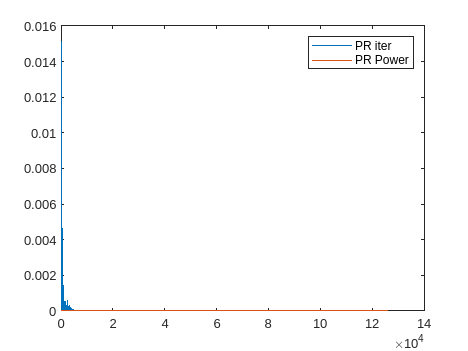

plot(pr_iter);
hold on
plot(pr_pi)
%plot(pr_eq)
%plot(pr_eig)
legend("PR iter", "PR Power");

hold off

### Calculate Sensitivity

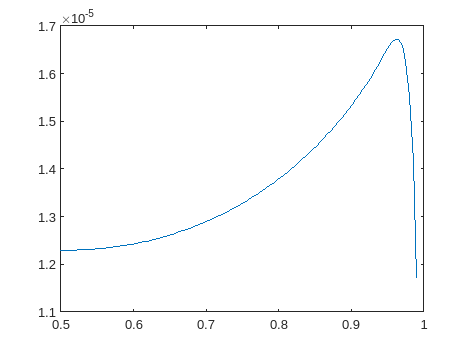

%Test variables
tests = 100;
alphas = linspace(0.5, 0.99, tests);
k = 100;
n = length(A_SG);

%Make a column vector of 1's normalized to n
v = eye(n, 1) / n;

%Initialize the S matrix
S = zeros(n, tests);

cnt = 1;
for alpha = alphas
    partial = A_SG*v;
    s_sum = 2*partial;

    for i = 2:k
        partial = alpha*A_SG*partial;
        s_sum = s_sum + (i+1)*partial;
    end

    s = -(1- alpha)*s_sum;
    
    S(:,cnt) = s;

    cnt = cnt + 1;
end

plot(alphas, max(abs(S)))

## FIRST 1000 SIGNGULAR VALUES USING RSVD

%Step 2
%Pull the size of the matrix
Asize = size(A_SG);
%m is x axis
m = Asize(1);
%n is y axis
n = Asize(2);
%Problem says find the first 1000 singular values using RSVD so r is 1100 oversample a bit
r = 1100;
%Create a random matrix that is n x r
X = randn(n,r);
%Multiply the matrices together to get AX
q = orth(A_SG*X);
%Do the QR factorization of AX to AX = QR
QTA = q'*A_SG

QTA =    -0.0195   -0.0195    0.0035   -0.0030   -0.0017    0.0077    0.0003   -0.0090   -0.0088   -0.0078    0.0055   -0.0029    0.0046   -0.0002   -0.0017   -0.0077   -0.0007   -0.0053   -0.0139    0.0030    0.0077   -0.0022    0.0062   -0.0003    0.0020   -0.0080   -0.0035   -0.0034    0.0104    0.0021    0.0034   -0.0076    0.0018    0.0086    0.0055   -0.0009   -0.0007    0.0052   -0.0007   -0.0102   -0.0086    0.0068    0.0012    0.0043   -0.0025   -0.0025    0.0026   -0.0040    0.0001   -0.0021
   -0.0070   -0.0070    0.0029   -0.0034   -0.0000   -0.0019    0.0021    0.0032    0.0005    0.0010   -0.0007    0.0008   -0.0023    0.0040    0.0048    0.0062   -0.0015    0.0051   -0.0021    0.0038   -0.0019    0.0001   -0.0041   -0.0044   -0.0001    0.0026    0.0125   -0.0002   -0.0012   -0.0069   -0.0053    0.0067    0.0001   -0.0057   -0.0109    0.0071   -0.0006   -0.0050    0.0041   -0.0069    0.0014   -0.0062   -0.0049    0.0077    0.0032   -0.0070    0.0024    0.0014    0.0008   

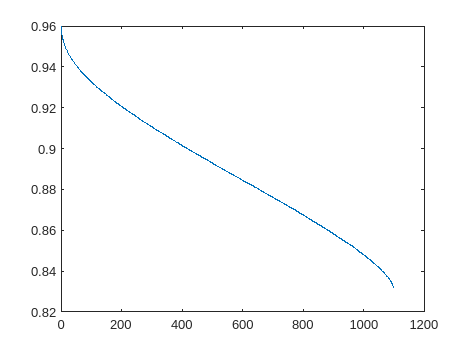

%Take the SVD of QTA
[uo,so,vot] = svd(QTA,"econ");
%Take the diagonal of the 
singvals = diag(so);
%figure(10)
plot(singvals)

## Minimal Route From 1000 to 1100:


src = 1000;
dest = 1100;
n = length(A_SG);

%Start at node 1000
startpoint = 1000;

%End at node 1100
endpoint = 1100;

%Make a sparse vector
S = sparse(n,1);

%Index the sparse matrix using the endpoint
S(endpoint,1) = 1;

%Multiply the matrix by the sparse matrix
PA = A_SG * S;

%Initialize distance
dist = 1;

while PA(startpoint, 1) == 0
    PA = A_SG * PA;
    dist=dist+1;
end

dist

dist = 140

## Split Graph with Fielder Method

L_SG = laplacian(SG);

[V_LSG, L_LSG, f_LSG] = eigs(L_SG,100,0);

Fiedler = V_LSG(:,2);

%Find the minimum of S that isn't ~zero
%[M, I] = min(s_SG(abs(s) > 1e-10));

%Fiedler = D_SG(:,I);
sum(Fiedler)

ans = 9.4670e-11


Positions = 1:height(SG.Nodes);

Cut = Fiedler > 0;

SG_1_nodes = Positions(Cut);
SG_2_nodes = Positions(~Cut);


## Plot the Cuts

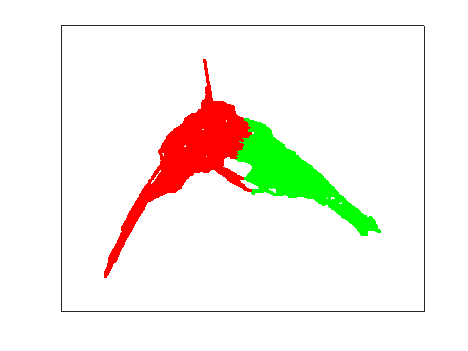

SG_plot = plot(SG);

%plot(SG)
highlight(SG_plot,SG_1_nodes,'NodeColor','r');
highlight(SG_plot,SG_2_nodes,'NodeColor','g');

## G49.mat

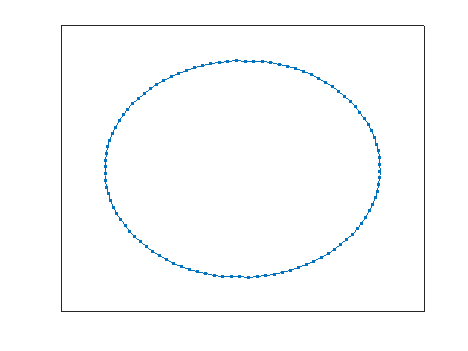

load('G49.mat')

Graph_G49 = graph(Problem.A);
plot(Graph_G49)

## Calculate PageRank

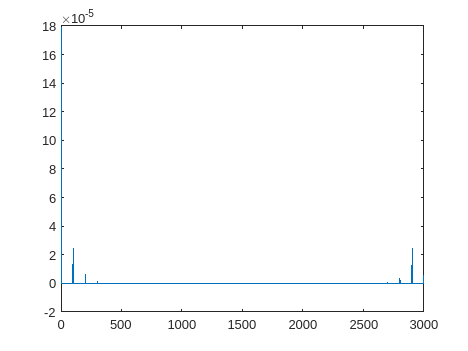

A_G49 = full(Problem.A);

A_G49 = A_G49 ./sum(A_G49);

alpha = 0.5;
n = length(A_G49);

pr = ((1-alpha)/n)*pinv(eye(n,n) - alpha*A_G49)*eye(n,1);
plot(pr)

## Cut Graph

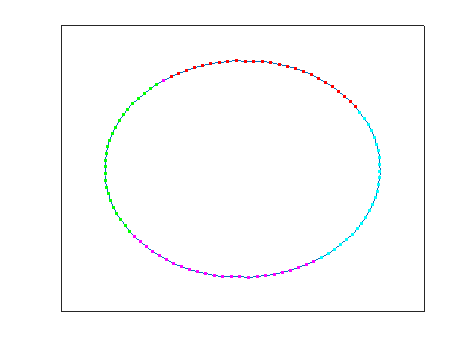


L = laplacian(Graph_G49);
[D, S] = eigs(L, 3000);

Positions = 1:height(L.Nodes);

s = diag(S);

%Find the minimum of S that isn't ~zero
[M, I] = min(s(abs(s) > 1e-15));

Cut = D(:,I) > 0;

H1_nodes = Positions(Cut);
H2_nodes = Positions(~Cut);

H1 = rmnode(Graph_G49, H1_nodes);
H2 = rmnode(Graph_G49, H2_nodes);

G_plot = plot(Graph_G49);
highlight(G_plot,H1_nodes,'NodeColor','g');
highlight(G_plot,H2_nodes,'NodeColor','r')

% Split the first half in two
L1 = laplacian(H1);
n1 = height(H1.Nodes);
[D1, S1] = eigs(L1, n1);

Pn1 = 1:n1;

s1 = diag(S1);

%Find the minimum of S that isn't ~zero
[M1, I1] = min(s1(abs(s1) > 1e-10));

Cut1 = D1(:,I1) > 0;

H11 = rmnode(H1, Pn1(~Cut1));
H12 = rmnode(H1, Pn1(Cut1));

H11_nodes = H1_nodes(Cut1);
H12_nodes = H1_nodes(~Cut1);

highlight(G_plot,H11_nodes,'NodeColor','magenta');

% Split the second half in two
L2 = laplacian(H2);
n2 = height(H2.Nodes);
[D2, S2] = eigs(L2, n2);

Pn2 = 1:n2;

s2 = diag(S2);

%Find the minimum of S that isn't ~zero
[M2, I2] = min(s2(abs(s2) > 1e-10));

Cut2 = D1(:,I2) > 0;

H21 = rmnode(H2, Pn2(~Cut2));
H22 = rmnode(H2, Pn2(Cut2));

H21_nodes = H2_nodes(Cut2);
H22_nodes = H2_nodes(~Cut2);

highlight(G_plot,H21_nodes,'NodeColor','cyan');

### Find the Dirichlet PageRank

An_G49 = full(Problem.A ./ sum(Problem.A))

An_G49 =          0    0.2500         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.2500         0    0.2500         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0

n = length(H22_nodes);
alpha = 0.5;

A21 = An_G49(H22_nodes,H22_nodes);
A22 = An_G49(H21_nodes,H21_nodes);

Adir = [A21,A22;
        A22,A21];

Adir = Adir./sum(Adir);

xdir=inv(eye(n) - alpha*A22) * ((1-alpha)*ones(n,1)+alpha*A21*ones(n,1)/n)

xdir =     0.8293
    0.9718
    0.9963
    1.0005
    1.0012
    1.0013
    1.0013
    1.0013
    1.0013
    1.0013


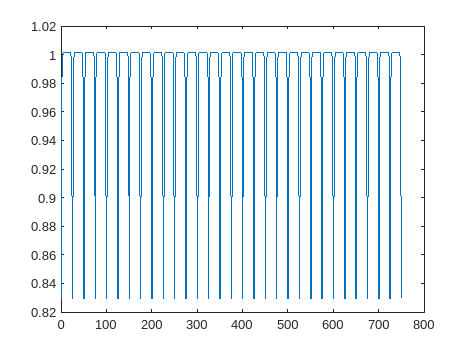

plot(xdir)